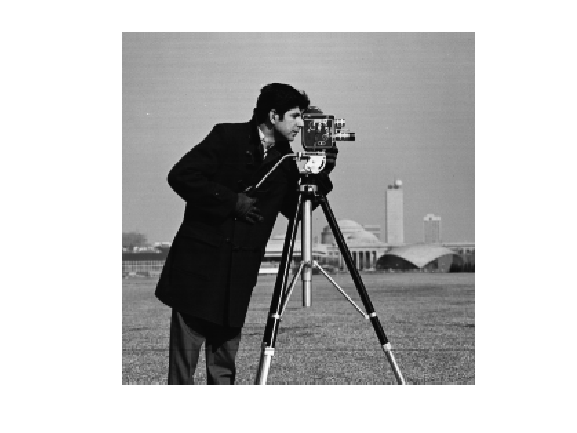

Inp = imread('cameraman.tif');
imshow(Inp)

[M2]=size(Inp,1)*2;
[N2]=round(size(Inp,2)*1.6);
[M,N]=size(Inp);
T1=[2,0,0;0,1.6,0;0,0,1]

T1 =     2.0000         0         0
         0    1.6000         0
         0         0    1.0000


T_inv=inv(T1)

T_inv =     0.5000         0         0
         0    0.6250         0
         0         0    1.0000



for row=1:M2;
    for col=1:N2;
        Ori_Coor=T_inv*[row, col,1]';
        if mod(Ori_Coor(1),1) == 0 & mod(Ori_Coor(2),1) == 0
            Outp(row, col)=Inp(Ori_Coor(1),Ori_Coor(2));
        elseif mod(Ori_Coor(1),1) == 0 & Ori_Coor(2)>1 & Ori_Coor(2)<= N
            a=Inp(Ori_Coor(1),ceil(Ori_Coor(2)));
            b=Inp(Ori_Coor(1),floor(Ori_Coor(2)));
            dif_y=Ori_Coor(2)-floor(Ori_Coor(2));
            dif_yplus1=ceil(Ori_Coor(2))-Ori_Coor(2);
            Outp(row, col)=a*dif_y+b*dif_yplus1;
        elseif mod(Ori_Coor(2),1) == 0 & Ori_Coor(1)>1 & Ori_Coor(1)<=M
            a=Inp(ceil(Ori_Coor(1)),Ori_Coor(2));
            b=Inp(floor(Ori_Coor(1)),Ori_Coor(2));
            dif_x=Ori_Coor(1)-floor(Ori_Coor(1));
            dif_xplus1=ceil(Ori_Coor(1))-Ori_Coor(1);
            Outp(row, col)=a*dif_x+b*dif_xplus1;
            
        elseif  Ori_Coor(1)>1 & Ori_Coor(2)>1 & Ori_Coor(1)<=M & Ori_Coor(2)<= N
            a=Inp(ceil(Ori_Coor(1)),ceil(Ori_Coor(2)));
            b=Inp(floor(Ori_Coor(1)),ceil(Ori_Coor(2)));
            c=Inp(ceil(Ori_Coor(1)),floor(Ori_Coor(2)));
            d=Inp(floor(Ori_Coor(1)),floor(Ori_Coor(2)));
            dif_x=Ori_Coor(1)-floor(Ori_Coor(1));
            dif_xplus1=ceil(Ori_Coor(1))-Ori_Coor(1);
            dif_y=Ori_Coor(2)-floor(Ori_Coor(2));
            dif_yplus1=ceil(Ori_Coor(2))-Ori_Coor(2);
            Outp(row, col)=(d*dif_xplus1*dif_yplus1+c*dif_x*dif_yplus1+b*dif_xplus1*dif_y+a*dif_y*dif_x);
            
        else
            Outp(row, col)=256;
        end
        

    end
end
Outp=uint8(Outp)

Outp = 512×410 uint8 matrix
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   157   159   159   157   156   156   158   157   157   159   159   158   158   157   158   158   159   159   160   160   160   160   160   159   160   163   163   161   162   161   160   163   163   161   163   164   163   162   161   162   162   161   163   165   165   164   162   162   162
   255   159   158   159   158   159   158   158   159   159   159   160   158   159   158   159   158   158   159   159   160   160   159   160   158   160   164   164   161   162   162   159   162   164   161   164   164   164   162   161   162   164   163   164   165   166   164   164   165   167
   255   159   155   156   157   158   158   157   158   159   158   

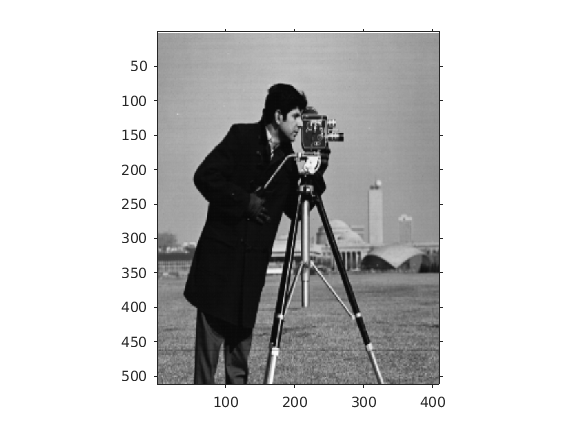

figure;  imshow(Outp);axis on